Create database!

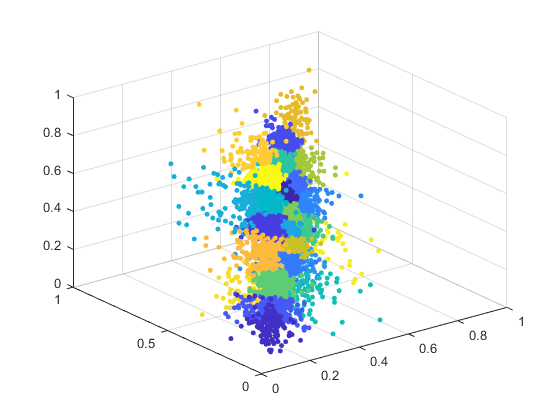

numberOfCluster = 25;
clusterSize = 4; 
tinyImgSize = 24; 

[smallDatabase, meanSmallDB] = filtering(numberOfCluster,clusterSize,tinyImgSize);

Create reconstructed image from smaller images that comes from the database

% Name of the file (Must be of type jpg)
fileName = 'OP.jpg';
% The size for each "cell" that goes through the image. Recommended size = 8
cellSize = 8;
% Number of 'good-matches' to use SSIM on. Higher = better quality (but also more compute heavy)
n = 3;

% call function to create image
[imgOUT, imgSSIM, imgSNR, imgDE] = image_rec_v1(fileName, smallDatabase, meanSmallDB, cellSize, n);

Image dimensions are not divisible by:8
The size of the image has been changed to:176x304
Some information from the original image has therefore been lost
SSIM:0.000360
SNR:0.050746
DELTA E:4011.415894
Elapsed time 


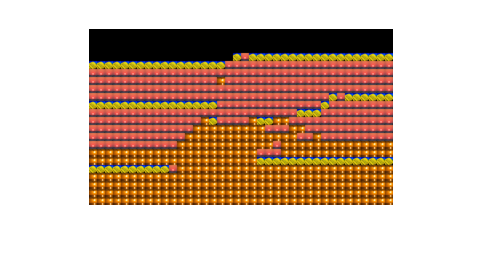


% show the final image
imshow(lab2rgb(imgOUT))